# Constrained Polynomial Zonotope

In CORA, constrained polynomial zonotopes are instantiated by 

% cPZ = conPolyZono(c,G,E,A,b,EC,GI);

where `c` is the start point, `G` is the generator matrix with dependent factors, `E` is the exponent matrix, `A` is the constraint matrix, `b` is the constraint offset, EC is the constraint exponent matrix, and G`I` is the generator matrix with independent factors.

Example:

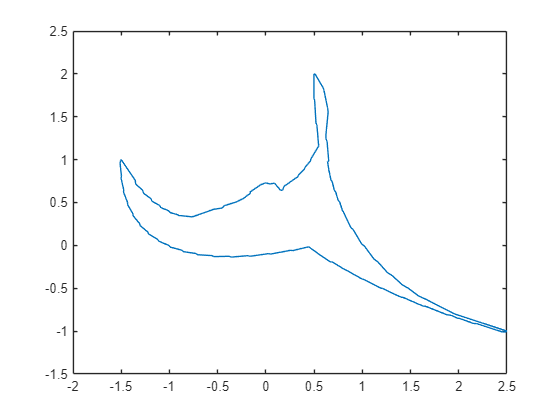

% initialize constrained polynomial zonotope
c = [0;0];
G = [1 0 1 -1; 0 1 1 1];
E = [1 0 1 2; 0 1 1 0; 0 0 1 1];
A = [1 -0.5 0.5];
b = 0.5;
EC = [0 1 2; 1 0 0; 0 1 0];
cPZ = conPolyZono(c,G,E,A,b,EC);

% plot constrained polynomial zonotope
plot(cPZ);

For more information, type

help conPolyZono

  conPolyZono - class definition for constrained polynomial zonotopes 
 
  Syntax:
     obj = conPolyZono(c)
     obj = conPolyZono(c,G,E)
     obj = conPolyZono(c,G,E,GI)
     obj = conPolyZono(c,G,E,GI,id)
     obj = conPolyZono(c,G,E,A,b,EC)
     obj = conPolyZono(c,G,E,A,b,EC,GI)
     obj = conPolyZono(c,G,E,A,b,EC,GI,id)
 
  Inputs:
     c - constant offset (dimension: [n,1])
     G - generator matrix (dimension: [n,h])
     E - exponent matrix (dimension: [p,h])
     A - constraint generator matrix (dimension: [m,q])
     b - constraint offset (dimension: [m,1])
     EC - constraint exponent matrix (dimension: [p,q])
     GI - generator matrix of independent generators (dimension: [n,v])
     id - vector containing the integer identifiers for all factors
          (dimension: [p,1])
 
  Outputs:
     obj - conPolyZono object
 
  